# MATLAB workshop

v.0.1.1 Evgeny Kolonsky 2025

- Plotting data: points, errorbars, scale

- Linear regression fit

- Importing and fitting data with masters

clc; clear all; close all;

## Plotting 

### Plotting simple data

Let's take some measurements stored it in vectors $x$ and $y$ and display the data on a graph.

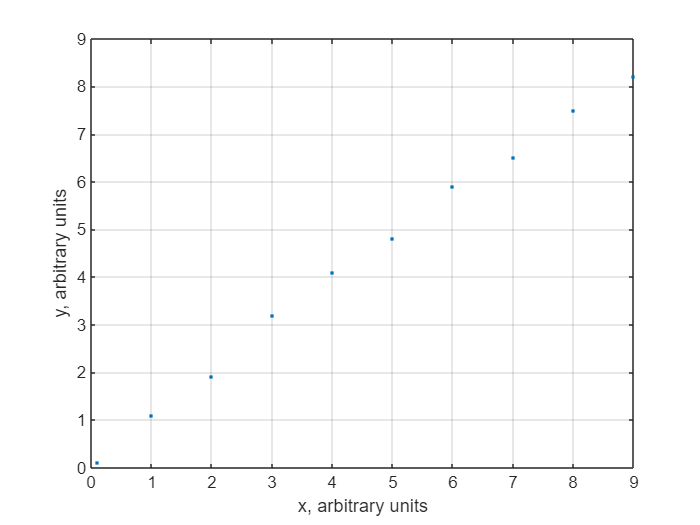

% synthetic data
x = [0.1 1   2   3   4   5   6   7   8   9]; 
y = [0.1 1.1 1.9 3.2 4.1 4.8 5.9 6.5 7.5 8.2]; 

figure
plot(x, y, '.')
grid on
xlabel('x, arbitrary units')
ylabel('y, arbitrary units')

### Plotting data with errorbars

Assume now that we know relative error for $y$ measurements and absolute error for $x$. We can plot the data with error bars using function `errorbar`. 

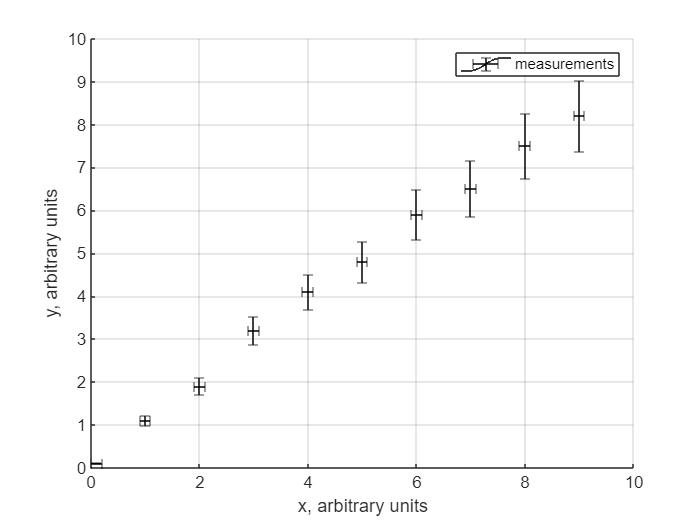

% uncertainties
y_err_relative = 0.1; %s 10 percent relative error
y_err = y .* y_err_relative; % absolute error
x_err = 0.10; % abs error for all values
figure
hold on
errorbar(x, y, y_err, y_err, x_err, x_err, color='k')
hold off
legend('measurements')
grid on

xlabel('x, arbitrary units')
ylabel('y, arbitrary units')

### Plotting data in log axis

The graph can be shown in log axis. Note that errorbars scaled automatically.

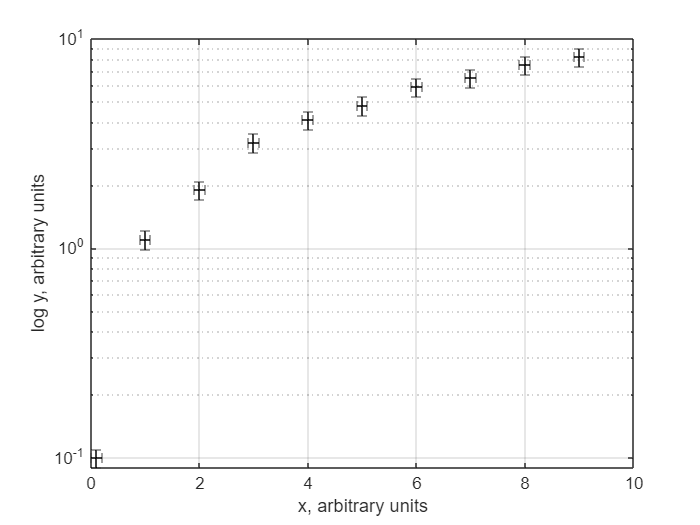

figure
errorbar(x, y, y_err, y_err, x_err, x_err, color='k')
grid on

xlabel('x, arbitrary units')
ylabel('log y, arbitrary units')
yscale('log')

## Linear regression fitting

see חוברת אנליזת נתונים ע'13

Let's build linear regression model $y = a x + b$ and plot fitted linear regression on the same graph.  We use `fitlm` function for building linear regression model. 

We use `hold on`  command to plot both measured data with error bars and linear regression model on the same figure. We also need to add explanatory legend to the figure.

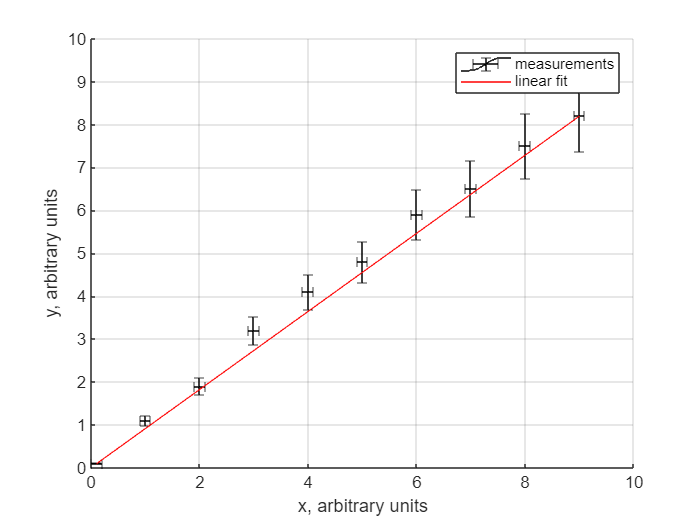

linear_regression = fitlm(x, y);
R_squared = linear_regression.Rsquared.Ordinary;
b_coefficient = linear_regression.Coefficients.Estimate(1);
a_coefficient = linear_regression.Coefficients.Estimate(2);
b_error = linear_regression.Coefficients.SE(1);
a_error = linear_regression.Coefficients.SE(2);
figure
hold on
plot1 = errorbar(x, y, y_err, y_err, x_err, x_err, color='k');
plot2 = plot(x, x * a_coefficient,'r');

legend([plot1(1), plot2(1)], 'measurements', 'linear fit')
grid on
xlabel('x, arbitrary units')
ylabel('y, arbitrary units')

Linear regression line crosses most of error bars, therefore data with her uncertainties fits linear model.

#### Task 1: rebuild graph for realtive error of $y$ is 1%. Does the data fits linear model now?

% place your code here

## Importing data from a file

Import and plot raw data

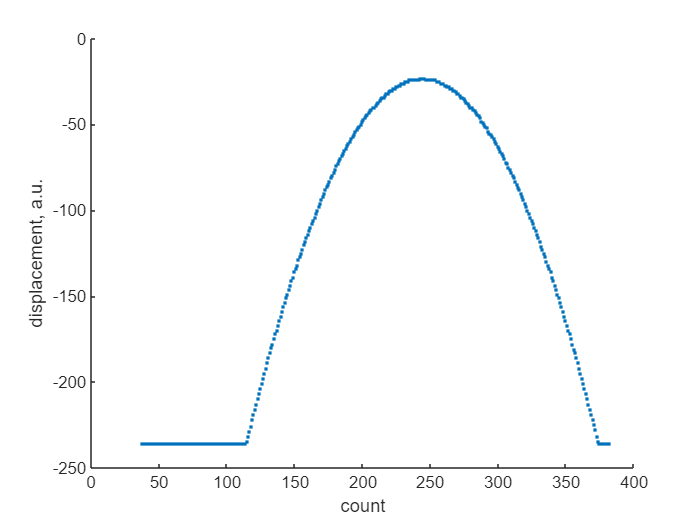

% import measurements to vectors 

% place your data path here
url = "https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/parabola.txt"; 
data = readmatrix(url);
ix = data(:,1); % ix in column 2
t = data(:,2); % time in column 2
x = data(:,4); % displacent in column 2
figure
hold on
plot(ix, x, '.')
ylabel('displacement, a.u.')
xlabel('count')

Cut parabola for further analysis

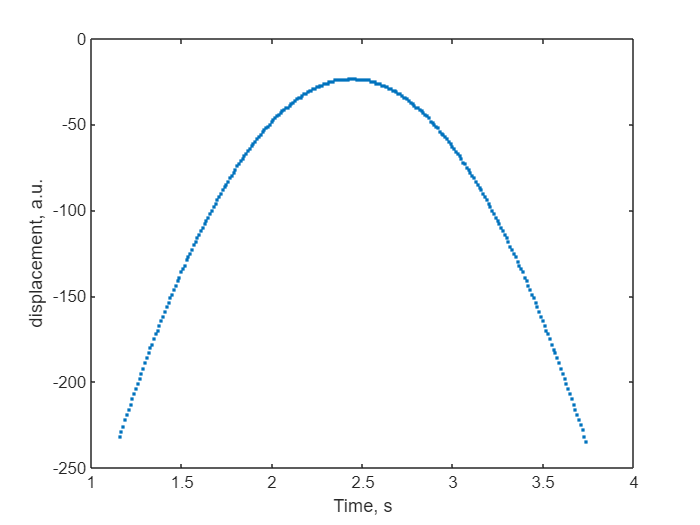

ix1 = 115;
ix2 = 375;
filter = (ix > ix1) & (ix < ix2);
t_ = t(filter);
x_ = x(filter);

figure
plot(t_, x_, '.')
ylabel('displacement, a.u.')
xlabel('Time, s')

Plot velocity as discrete derivative of displacement

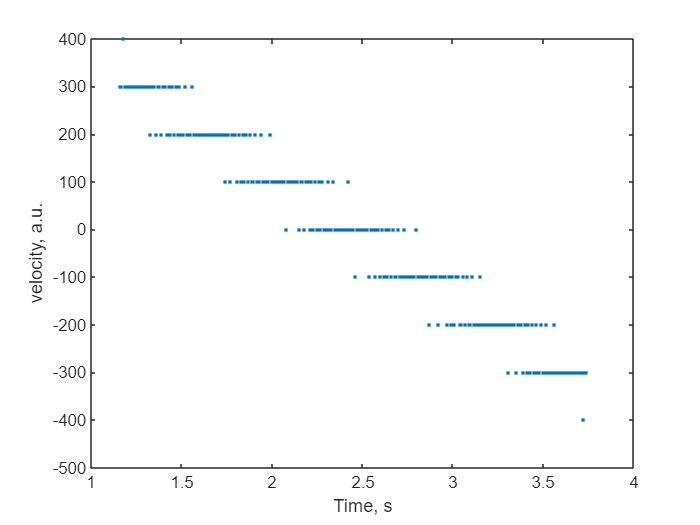

v_ = diff(x_) ./ diff(t_);
v_(end+1) = v_(end); % add element to align vector's length

figure
plot(t_, v_, '.')
ylabel('velocity, a.u.')
xlabel('Time, s')

#### Task 2: Plot linear regression of velocity $v$ vs. time $t$

% place your code here..

## Importing and fitting data with masters

Data load can also be done without lines of code by `Import data`  master .

Data fitting with linear or non-linear model can also be done with Curve Fitter App . Curve Fitter is an application to fit linear, polynomial, tringonometric, exponential functions as well as custom defined functions.

Let's try them.

### Task 3.1 Import vectors [$t$, count] from file, cut data and and build parabolic fit

- Download data to local disk drive [https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/parabola.txt](https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/parabola.txt) 

- Import Data using master

- Fit using Curve Fitter Find coefficients of 2nd degree polynom with their uncertainties. Cut parabola using `Exclude outliers` action.

% place your answer here

### Task 3.2 Import vector$t$ from file and build distribution histogram

- Download data to local drive [https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/pasco_sensor.txt](https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/pasco_sensor.txt)

- Import

- Plot histogram using function `histfit`.

% place your answer here

### Task 3.3 Import vectors [$t$, `count]` from file and find oscillations parameters with Curve Fitter App

- Download to local drive [https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/oscillations.txt](https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_Matlab_workshop/oscillations.txt)

- Import data

- Fit with sine function 

- Find oscillations frequency $\omega$ with it's uncertainties

% place your answer here